## Taller minimos cuadrados ordinarios


$$$$
\Phi=\left[\begin{array}{l}
\phi^T(4) \\
\phi^T(5) \\
\phi^T(6) \\
\phi^T(7)
\end{array}\right]=\left[\begin{array}{ccccc}
y(3) & u(3) & u(2) & u(1) & u(0) \\
y(4) & u(4) & u(3) & u(2) & u(1) \\
y(5) & u(5) & u(4) & u(3) & u(2) \\
y(6) & u(6) & u(5) & u(4) & u(3)
\end{array}\right]
$$
$$


clf
Datos = [0 1 0.0052;
         1 1 2.1190;
         2 1 1.4082;
         3 1 1.1868;
         4 1 1.2544;
         5 1 1.2402;
         6 1 1.2463;
         7 1 1.2448];
[phi, Y, param, cova] = OLS(Datos, 1, 4, 1);

%Notar que phi no esta bien definida, por lo que phi'*phi no tiene inversa 
phi , R = phi'*phi/(length(Datos))

phi =    -1.1868    1.0000    1.0000    1.0000    1.0000
   -1.2544    1.0000    1.0000    1.0000    1.0000
   -1.2402    1.0000    1.0000    1.0000    1.0000
   -1.2463    1.0000    1.0000    1.0000    1.0000


R =     0.7592   -0.6160   -0.6160   -0.6160   -0.6160
   -0.6160    0.5000    0.5000    0.5000    0.5000
   -0.6160    0.5000    0.5000    0.5000    0.5000
   -0.6160    0.5000    0.5000    0.5000    0.5000
   -0.6160    0.5000    0.5000    0.5000    0.5000



$$$$
\Phi=\left[\begin{array}{l}
\phi^T(1) \\
\phi^T(2) \\
\phi^T(3) \\
\phi^T(4) \\
\phi^T(5) \\
\phi^T(6) \\
\phi^T(7)
\end{array}\right]=\left[\begin{array}{ccccc}
y(0) & u(0) & u(-1) & u(-2) & u(-3) \\
y(1) & u(1) & u(0) & u(-1) & u(-2) \\
y(2) & u(2) & u(1) & u(0) & u(-1) \\
y(3) & u(3) & u(2) & u(1) & u(0) \\
y(4) & u(4) & u(3) & u(2) & u(1) \\
y(5) & u(5) & u(4) & u(3) & u(2) \\
y(6) & u(6) & u(5) & u(4) & u(3)
\end{array}\right]
$$
$$


%Por eso se le añade 3 datos en el que el sistema esta estacionario para
%poder que phi quede definida correctamente
clf
Datos = [-3 0 0;
         -2 0 0;
         -1 0 0;      
         Datos(:,1) Datos(:,2) Datos(:,3)];
[phi, Y, param, cova] = OLS(Datos, 1, 4, 1);

G = tf(param(2:end)',[1 param(1) 0 0 0],'ts',1)

G =
 
  2.12 z^3 - 0.3174 z^2 - 0.3537 z + 0.02682
  ------------------------------------------
               z^4 + 0.1861 z^3
 
Sample time: 1 seconds
Discrete-time transfer function.



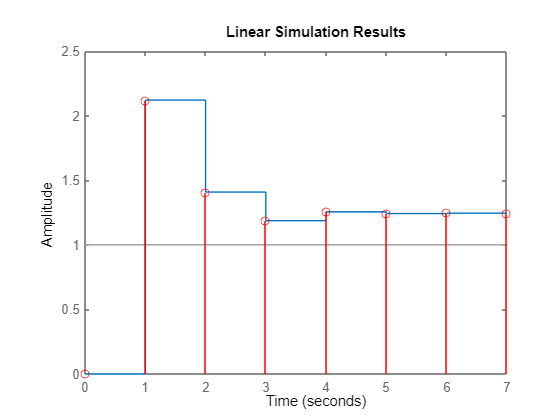

lsim(G,ones(8,1),linspace(0,7,8))
hold on
stem(Datos(4:end,1),Datos(4:end,3),"Color",'r')

sqrt(diag(cova)) %Desviacio estandar de los parametros

ans =     0.0391
    0.0021
    0.0828
    0.0280
    0.0073


data = iddata(Y,phi(:,end),1);
orden_excit = pexcit(data)%orden de excitacion del modelo

orden_excit = 3

%arx 112(pero con una estructura incorrecta)
clf
Datos = [0 1 0.0017;
         1 1 0.0060;
         2 1 1.2366;
         3 1 1.6391;
         4 1 1.7297;
         5 1 1.7490;
         6 1 1.7466;
         7 1 1.7433];
[phi, Y, param, cova] = MCO(Datos, 1, 1, 2);
%Notar que phi no esta bien definida, por lo que phi'*phi no tiene inversa 
phi, inv(phi'*phi)

phi =    -0.0060    1.0000
   -1.2366    1.0000
   -1.6391    1.0000
   -1.7297    1.0000
   -1.7490    1.0000
   -1.7466    1.0000


ans =     0.4231    0.5717
    0.5717    0.9391


G = tf(param(2:end)',[1 param(1) 0],'ts',1)

G =
 
      1.244
  --------------
  z^2 - 0.2933 z
 
Sample time: 1 seconds
Discrete-time transfer function.



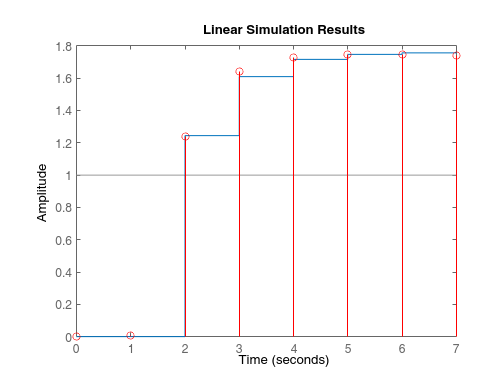

lsim(G,ones(8,1),linspace(0,7,8))
hold on
stem(Datos(:,1),Datos(:,3),"Color",'r')

Taller variable Instrumental

## Taller Filtros de Kalmann

### Punto 1


$$$\dot{\mathbf{x}}=\left[\begin{array}{cc}2 & 0 \\ -3 & 3\end{array}\right] \mathbf{x}+\left[\begin{array}{l}1 \\ 3\end{array}\right] u \quad y=\left[\begin{array}{ll}9 & -3\end{array}\right] \mathbf{x}$$$


A = [2 0; -3 3]; B = [1 3]';  C = [9 -3]; D = [0]

D = 0

%recordar que el calculo de la matriz de observabilidad es [C; C*A; C*A^2;...; C*A^n] donde n = #estados - 1
obs = obsv(A, C); 
rank(obsv(A,C)) %Es observable si el rango = #estados

ans = 1

cond(obs) %Es invertible si el numero de condicion no es muy alto

ans = 3.6948e+16

%El sistema no es observable, por tanto no se podria reconstruir a partir
%de finitas observaciones.



$$$\dot{\mathbf{x}}=\left[\begin{array}{ll}2 & 0 \\ 0.02 & 1\end{array}\right] \mathbf{x}+\left[\begin{array}{l}0 \\ 1\end{array}\right] u \quad y=x_2$$$


A = [2 0; 0.02 1]; B = [0 1]';  C = [0 1]; D = 0;

obs = obsv(A,C)

obs =          0    1.0000
    0.0200    1.0000


rank(obs), cond(obs)

ans = 2

ans = 100.0100


$$$\dot{\mathbf{x}}=\left[\begin{array}{ll}2 & 0 \\ 0 & 1\end{array}\right] \mathbf{x}+\left[\begin{array}{l}0 \\ 1\end{array}\right] u \quad y=x_1$$$


%Recordar que si en la salida solo se esta observando uno de los estados y
%ese estado no me da informacion del otro estado, el sistema no es
%observable ejemplo: 
%A = [2 0; 0 1]; B = [0 1]';  C = [1 0]; D = 0;


$$ $G(s)=\frac{s+3}{s^2+3 s+2}$$$


model = tf([1 3],[1 3 2],'ts',0);
model = ss(model)

model =
 
  A = 
       x1  x2
   x1  -3  -2
   x2   1   0
 
  B = 
       u1
   x1   2
   x2   0
 
  C = 
        x1   x2
   y1  0.5  1.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



A = model.A;  B= model.B; C = model.C; D = model.D;

obs = obsv(A,C)

obs =     0.5000    1.5000
         0   -1.0000


rank(obs), cond(obs)

ans = 2

ans = 6.8541

### **Punto 2**


$$$\left\{\begin{array}{l}\dot{x}_1=a x_1 x_2+u \\ \dot{x}_2=x_1^2-b x_1 x_2\end{array} \quad y=x_1 x_2\right.$$$


clf, clear all
syms a b u x1 x2
a = 1; b= 2;
ode1 = a*x1*x2 + u;
ode2 = x1^2 - b*x1*x2;

y = x1*x2;

odes = [ode1; ode2]; vars = [x1, x2];

[A, B, C, D] = linealizacion(odes,y,vars,u)

$$A = \left(\begin{array}{cc} x_{2} & x_{1}\\ 2\,x_{1}-2\,x_{2} & -2\,x_{1} \end{array}\right)$$

$$B = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

$$C = \left(\begin{array}{cc} x_{2} & x_{1} \end{array}\right)$$

D = 0

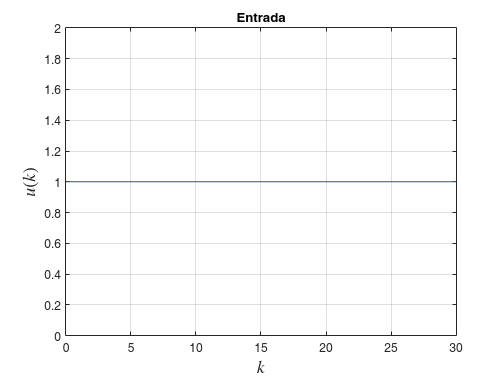


Ts = 0.1; % tiempo de muestreo T.
tiempo = 0:Ts:20; % periodo de tiempo a usar.
u = sin(4*tiempo) + randn(1,length(tiempo)); %ones(1, length(tiempo));

plot(tiempo, u)
title('Entrada');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$u(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
grid on

% Condiciones iniciales dados por el usuario:
M = 0.001*eye(2); R=0.5; P0 = M; x0 = [1 1]'; Ts = 0.1;
odes = matlabFunction(odes);

obs = obsv(subs(A,{'x1', 'x2'},{x0(1), x0(2)}),subs(C,{'x1', 'x2'},{x0(1), x0(2)}))

obs =      1     1
     1    -1


rank(obs), cond(obs)

ans = 2

ans = 1.0000

%Obtenemos los valores de y reales en cada tiempo t
[t, x] = ode45(@(t,x) ode(t, x, u, tiempo, odes), tiempo, x0); 

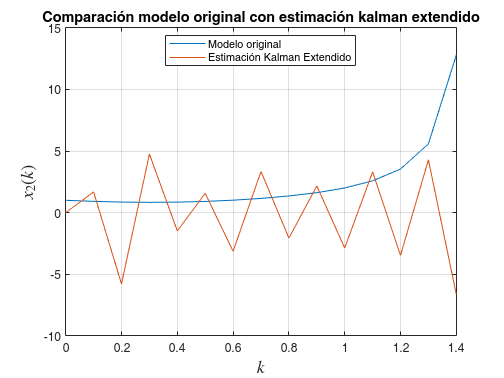

y = x(:,1);

KalmanExtended(A,C,odes,t,x,u,y,x0,M,R,P0,Ts);


$$$\left\{\begin{array}{l}\dot{x}_1=x_2 \\ \dot{x}_2=-x_1+\varepsilon\left(1-x_1^2\right) x_2\end{array} \quad y=x_1\right.$$$


clear all, clf, clc
syms x1 x2 u
epsilon = 0.1; %Constantes definidas por el usuario

ode1 = x2 +0*u;
ode2 = -x1+epsilon*(1-x1^2)*x2;
y = x1;

odes = [ode1; ode2]; vars = [x1, x2];

[A, B, C, D] = linealizacion(odes,y,vars,u)

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{x_{1}\,x_{2}}{5}-1 & \frac{1}{10}-\frac{{x_{1}}^{2}}{10} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

$$C = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

D = 0

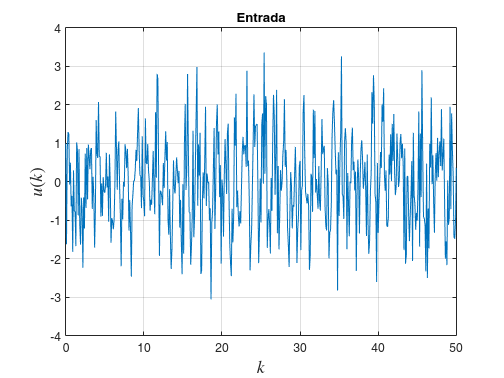

Ts = 0.1; % tiempo de muestreo T.
tiempo = 0:Ts:50; % periodo de tiempo a usar.
u = sin(5*tiempo) + randn(1,length(tiempo)); %ones(1, length(tiempo));

plot(tiempo, u)
title('Entrada');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$u(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
grid on

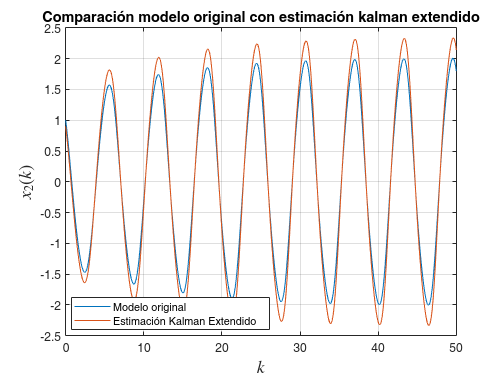

% Condiciones iniciales dados por el usuario:
M = 0.001*eye(2); R=0.5; P0 = M; x0 = [1 1]'; Ts = 0.1;
odes = matlabFunction(odes);
%Obtenemos los valores de y reales en cada tiempo t
[t, x] = ode45(@(t,x) ode(t, x, u, tiempo, odes), tiempo, x0); 
y = x(:,1);

KalmanExtended(A,C,odes,t,x,u,y,x0,M,R,P0,Ts);

Parciales Kalman


$$$\left(\begin{array}{l} \dot{x_1} = v-\mu \,x_{1}-\frac{\beta \,x_{1}\,x_{2}}{N}\\ \dot{x_2}= \frac{\beta \,x_{1}\,x_{2}}{N}-\mu \,x_{2}-x_{2}\,\left(\gamma +u\right)\\ \dot{x_3} = x_{2}\,\left(\gamma +u\right)-\mu \,x_{3} \end{array}\right. \quad y=x_1  \\ $$$


clear all, clf, clc
syms x1 x2 u a b c d 
a = 0.01; b = 0.02; c = 0.1; d = 0.2;
vars = [x1, x2];
odes = [-a*x1 + b*x1*x2; c*x1^2 - d*x2 + u];
y = x1; 

[A, B, C, D] = linealizacion(odes,y,vars,u)

$$A = \left(\begin{array}{cc} 0.0200\,x_{2}-0.0100 & 0.0200\,x_{1}\\ 0.2000\,x_{1} & -0.2000 \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

$$C = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

D = 0

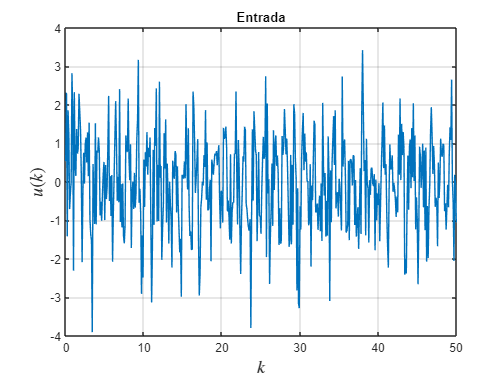

Ts = 0.1; % tiempo de muestreo T.
tiempo = 0:Ts:50; % periodo de tiempo a usar.
u = sin(5*tiempo) + randn(1,length(tiempo)); %ones(1, length(tiempo));

plot(tiempo, u)
title('Entrada');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$u(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
grid on

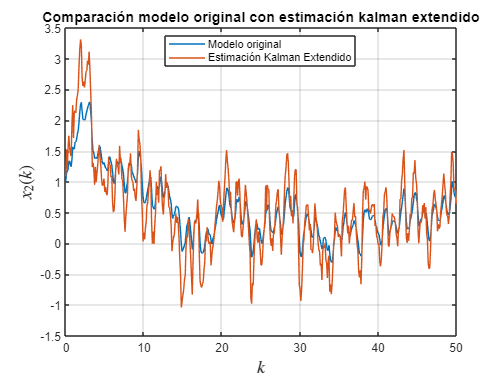

clf
% Condiciones iniciales dados por el usuario:
M = 1*eye(2); R=0.5; P0 = M; x0 = [1 1]'; Ts = 0.2;
%odes = matlabFunction(odes);
%Obtenemos los valores de y reales en cada tiempo t
[t, x] = ode45(@(t,x) ode(t, x, u, tiempo, odes), tiempo, x0); 
y = x(:,1);

V = 0.01*randn(length(y),2);
y = y + V;
KalmanExtended(A,C,odes,t,x,u,y,x0,M,R,P0,Ts,V);

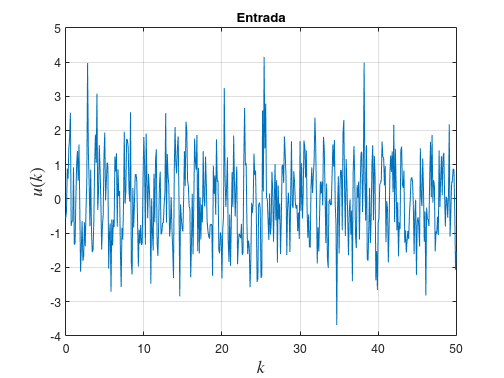


%% Punto 2
clear all, clf
syms x1 x2 u a b c d 
vars = [x1, x2];
odes = [-a*x1 + b*x1*x2; c*x1^2 - d*x2 + u];

% Revisamos que el Jacobiano esté bien:
J = jacobian(odes, vars);
syms T
A = eye(2) + J*T;
%A(T,x1,x2): función de la matriz del modelo linealizado y discretizado
A = matlabFunction(A); 
Ts = 0.1; % tiempo de muestreo T.
tiempo = 0:Ts:50; % periodo de tiempo a usar.
x0 = [1, 1]; % Condición inicial
% Probamos dos entradas:
u = sin(5*tiempo) + randn(1,length(tiempo));%ones(1, length(tiempo));%sin(5*tiempo) + randn(1,length(tiempo));
plot(tiempo, u)
title('Entrada');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$u(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
grid on

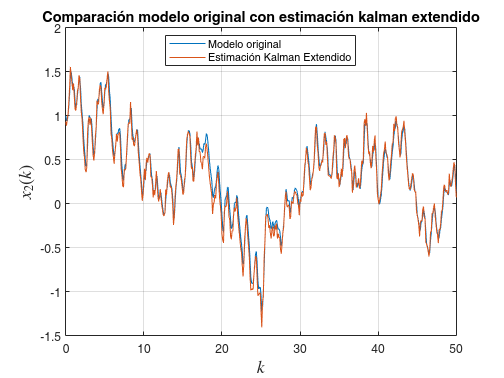

a = 0.01; b = 0.02; , c = 0.1; d = 0.2;
[t, x] = ode45(@(t,x) ode_parcial(t, x, u, tiempo, a, b, c, d), tiempo, x0);
y = x(:,1);
% Condiciones iniciales dados por el usuario:
M = 0.01*eye(2); N = 0.5; P0 = M; x0 = [1 1]'; Ts = 0.1;
% Parámetros conocidos:
C = [1 0];
n = length(y); x_est = zeros(n,2); P_trace = zeros(n,1); K_norm = zeros(n,1);
x_act = x0; P_act = P0;
for k = 1:n
    A_ = A(Ts,a,b,c,d,x_act(1), x_act(2));
    % Predicción:
    x_pred = [x_act(1) + Ts*(b*x_act(1)*x_act(2)-a*x_act(1));
              x_act(2) + Ts*(c*x_act(1)^2 - d*x_act(2) + u(k))];
    P_pred = A_*P_act*A_' + M;
    % Corrección:
    K = P_pred*C'*inv(C*P_pred*C' + N);
    x_act = x_pred + K*(y(k) - C*x_pred);
    P_act = (eye(2) - K*C)*P_pred;
    % Estimación:
    x_est(k,:) = x_act';
    % Medidas:
    P_trace(k) = trace(P_act);
    K_norm(k) = norm(K);
end
plot(t, x(:,2), t, x_est(:,2))
legend({'Modelo original', 'Estimación Kalman Extendido'}, 'Location', 'best');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$x_{2}(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
title('Comparación modelo original con estimación kalman extendido', 'FontSize', 12);
grid on

## Estudio Parciales

#### Punto 1

Originalmente el sistema es un arx 311 pero este no da entonces lo cambiamos a un arx 121 y le anadimos valores anteriores


$$$$
ARX 121 \quad \Phi=\left[\begin{array}{l}
\phi^T(1) \\
\phi^T(2) \\
\phi^T(3) \\
\phi^T(4) \\
\phi^T(5) \\
\phi^T(6) \\
\phi^T(7)
\end{array}\right]=\left[\begin{array}{ccc}
y(0) & u(0) & u(-1) \\
y(1) & u(1) & u(0) \\
y(2) & u(2) & u(1) \\
y(3) & u(3) & u(2) \\
y(4) & u(4) & u(3) \\
y(5) & u(5) & u(4) \\
y(6) & u(6) & u(5) 
\end{array}\right]
$$
$$


%punto 1
clf
t = 0:1:7; 
u = ones(1,8);
y = [0.0042 3.8009 3.0460 3.3867 3.3054 3.3347 3.3261 3.3226];

Datos = [t' u' y'];

Datos = [-1 0 0;      
         Datos(:,1) Datos(:,2) Datos(:,3)];

[phi, Y, param, cova] = OLS(Datos, 1, 2, 1);

G = tf([param(2:end)'],[1 param(1)' 0],'ts',1)

G =
 
  3.803 z + 1.086
  ---------------
  z^2 + 0.4757 z
 
Sample time: 1 seconds
Discrete-time transfer function.



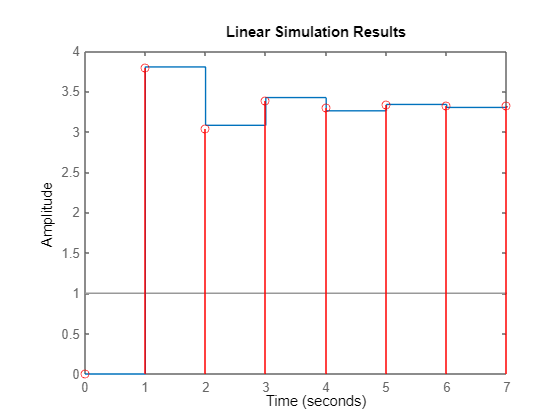

lsim(G,ones(1,8),0:1:7)
hold on
stem(Datos(2:end,1),Datos(2:end,3),"Color",'r')

#### Punto 2

t = 0:1:7; u = ones(8,1);
y = [0.0023 1.4297 1.2975 1.2658 1.2560 1.26 1.2545 1.2519];
Data = [t' u' y'];

